# Eclipse 🌑🌒🌓

Analyze the total solar eclipse

2024-04-08

## Context

In this tutorial, we will show how to use MATLAB with the SunPy community Python library for Solar Physics

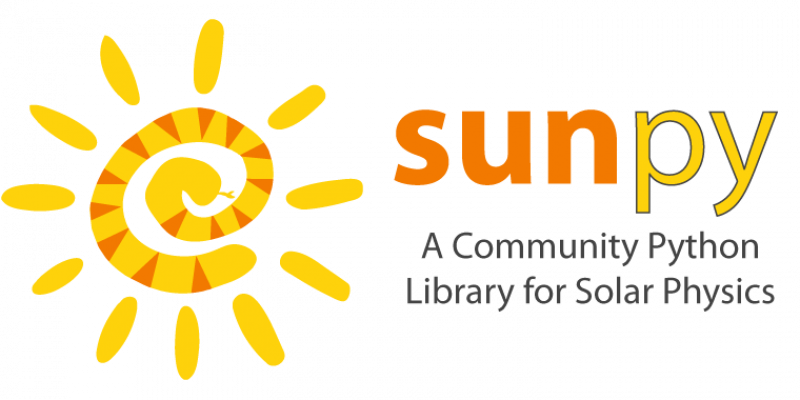

## Resources

- [https://github.com/yanndebray/matlab-with-python-book](https://github.com/yanndebray/matlab-with-python-book)

- [https://docs.sunpy.org/en/stable/generated/gallery/showcase/eclipse_amount.html](https://docs.sunpy.org/en/stable/generated/gallery/showcase/eclipse_amount.html) 

## Set up environment

setup

Defaulting to user installation because normal site-packages is not writeable
Requirement

pipshow("numpy")

Name: numpy
Version: 2.0.0
Summary: Fundamental package for array computing in Python
Home-page: https://numpy.org
Author: Travis E. Oliphant et al.
Author-email: 
License: Copyright (c) 2005-2024, NumPy Developers.
        All rights reserved.
        
        Redistribution and use in source and binary forms, with or without
        modification, are permitted provided that the following conditions are
        met:
        
            * Redistributions of source code must retain the above copyright
               notice, this list of conditions and the following disclaimer.
        
            * Redistributions in binary form must reproduce the above
               copyright notice, this list of conditions and the following
               disclaimer in the documentation and/or other materials provided
               with the distribution.
        
            * Neither the name of the NumPy Developers nor the names of any
               contributors may be used to endorse or promot

## Import data with Python live task

% run python file that returns latitude, longitude, and a pandas dataframe
% (lat, lon, df) respectively
[lat, lon, df] = pyrunfile("runpy.py", [ "latitude" "longitude" "df" ])

Eclipse detected:
  Partial solar eclipse starts at 2024-04-08 17:15:00.000 UTC
  Total solar eclipse starts at 2024-04-08 18:33:44.000 UTC
  Total solar eclipse ends at 2024-04-08 18:35:34.000 UTC
  Partial solar eclipse ends at 2024-04-08 19:55:00.000 UTC


lat =   Python Quantity:

   29.6000

    Use details function to view the properties of the Python object.

    Use double function to convert to a MATLAB array.


lon =   Python Quantity:

  -98.5000

    Use details function to view the properties of the Python object.

    Use double function to convert to a MATLAB array.


df =   Python DataFrame with properties:

          T: [1x1 py.pandas.core.frame.DataFrame]
         at: [1x1 py.pandas.core.indexing._AtIndexer]
      attrs: [1x1 py.dict]
       axes: [1x2 py.list]
    columns: [1x1 py.pandas.core.indexes.base.Index]
     dtypes: [1x1 py.pandas.core.series.Series]
      empty: 0
      flags: [1x1 py.pandas.core.flags.Flags]
        iat: [1x1 py.pandas.core.indexing._iAtIndexer]
       iloc: [1x1 py.pandas.core.indexing._iLocIndexer]
      index: [1x1 py.pandas.core.indexes.range.RangeIndex]
        loc: [1x1 py.pandas.core.indexing._LocIndexer]
       ndim: [1x1 py.int]
      shape: [1x2 py.tuple]
       size: [1x1 py.int]
     values: [1x1 py.numpy.ndarray]

                       time  amount  amount_minimum
    0   2024-04-08 16:35:00     0.0             0.0
    1   2024-04-08 16:36:00     0.0             0.0
    2   2024-04-08 16:37:00     0.0             0.

## Transform Pandas Dataframe to MATLAB Table

% T = table(df)
TT = timetable(df)

TT = 831x2 timetable
            time            amount    amount_minimum
    ____________________    ______    ______________

    08-Apr-2024 16:35:00      0             0       
    08-Apr-2024 16:36:00      0             0       
    08-Apr-2024 16:37:00      0             0       
    08-Apr-2024 16:38:00      0             0       
    08-Apr-2024 16:39:00      0             0       
    08-Apr-2024 16:40:00      0             0       
    08-Apr-2024 16:41:00      0             0       
    08-Apr-2024 16:42:00      0             0       
    08-Apr-2024 16:43:00      0             0       
    08-Apr-2024 16:44:00      0             0       
    08-Apr-2024 16:45:00      0             0       


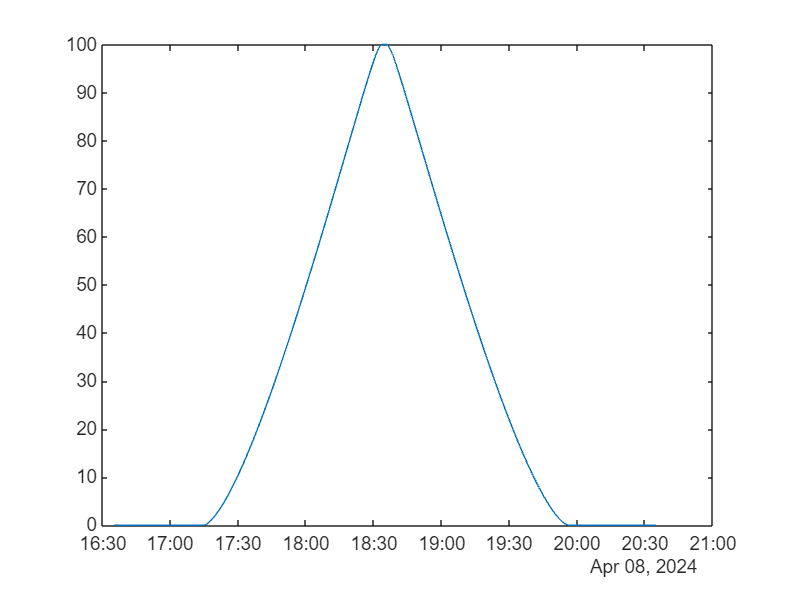

% stackedplot(TT)
plot(TT.time,TT.amount)

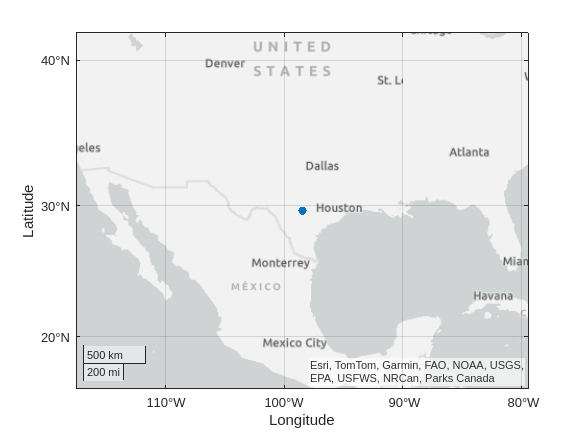

% San Antonio, Texas

lat = double(lat);
lon = double(lon);
geoscatter(lat,lon, 'filled')

## Export to ipynb and md

%export('livescript.mlx','README.md');
%export('livescript.mlx','notebook.ipynb');

## **For fun: Installing Python packages**

% install scikit-learn
pipinstall("scikit-learn")

Defaulting to user installation because normal site-packages is not writeable


% show the install
pipshow("scikit-learn")

Name: scikit-learn
Version: 1.5.1
Summary: A set of python modules for machine learning and data mining
Home-page: https://scikit-learn.org
Author: 
Author-email: 
License: new BSD
Location: /home/matlab/.local/lib/python3.10/site-packages
Requires: joblib, numpy, scipy, threadpoolctl
Required-by: 


% install scipy
pipinstall("scipy")

Defaulting to user installation because normal site-packages is not writeable


% show the install
pipshow("scipy")

Name: scipy
Version: 1.14.0
Summary: Fundamental algorithms for scientific computing in Python
Home-page: https://scipy.org/
Author: 
Author-email: 
License: Copyright (c) 2001-2002 Enthought, Inc. 2003-2024, SciPy Developers.
        All rights reserved.
        
        Redistribution and use in source and binary forms, with or without
        modification, are permitted provided that the following conditions
        are met:
        
        1. Redistributions of source code must retain the above copyright
           notice, this list of conditions and the following disclaimer.
        
        2. Redistributions in binary form must reproduce the above
           copyright notice, this list of conditions and the following
           disclaimer in the documentation and/or other materials provided
           with the distribution.
        
        3. Neither the name of the copyright holder nor the names of its
           contributors may be used to endorse or promote products derived